# PHASE 3 — Adaptive Filter Sweep for ALL Noise Levels

clear; clc; close all;

addpath(genpath('./src'));

% Noise Levels

noiseLevels = ["pn3", "pn5", "pn9"];

% Load clean reference slice

dataDir = "./data/raw/";
cleanFile = "t1_icbm_normal_1mm_pn0_rf0.nii";

cleanVol = load_brainweb_nifti(fullfile(dataDir, cleanFile));
slice_idx = round(size(cleanVol,3)/2);

% Normalize clean slice
clean = mat2gray(double(cleanVol(:,:,slice_idx)));

fprintf("Loaded and normalized clean slice.\n");

Loaded and normalized clean slice.


   SWEEPING PARAMETERS FOR pn3


w=5 | sigma=0.60 | var=0.70 -> PSNR=24.849 SSIM=0.8306 RMSE=0.0572
w=5 | sigma=0.60 | var=0.90 -> PSNR=24.933 SSIM=0.8379 RMSE=0.0567
w=5 | sigma=0.60 | var=1.00 -> PSNR=24.969 SSIM=0.8404 RMSE=0.0564
w=5 | sigma=0.60 | var=1.20 -> PSNR=25.032 SSIM=0.8451 RMSE=0.0560
w=5 | sigma=0.80 | var=0.70 -> PSNR=25.070 SSIM=0.8468 RMSE=0.0558
w=5 | sigma=0.80 | var=0.90 -> PSNR=25.159 SSIM=0.8534 RMSE=0.0552
w=5 | sigma=0.80 | var=1.00 -> PSNR=25.195 SSIM=0.8556 RMSE=0.0550
w=5 | sigma=0.80 | var=1.20 -> PSNR=25.261 SSIM=0.8598 RMSE=0.0546
w=5 | sigma=1.00 | var=0.70 -> PSNR=25.172 SSIM=0.8509 RMSE=0.0551
w=5 | sigma=1.00 | var=0.90 -> PSNR=25.251 SSIM=0.8560 RMSE=0.0546
w=5 | sigma=1.00 | var=1.00 -> PSNR=25.282 SSIM=0.8575 RMSE=0.0544
w=5 | sigma=1.00 | var=1.20 -> PSNR=25.339 SSIM=0.8607 RMSE=0.0541
w=5 | sigma=1.20 | var=0.70 -> PSNR=25.172 SSIM=0.8464 RMSE=0.0551
w=5 | sigma=1.20 | var=0.90 -> PSNR=25.259 SSIM=0.8517 RMSE=0.0546
w=5 | sigma=1.20 | var=1.00 -> PSNR=25.283 SSIM=0.8526 RMSE=0.


----- TOP 5 PARAMETER SETS FOR pn3 -----


    winSize    gaussSigma    varFactor     PSNR      SSIM        RMSE  
    _______    __________    _________    ______    _______    ________

       5            1           1.2       25.339    0.86068    0.054084
       5          1.2           1.2       25.325    0.85461    0.054172
       5          1.4           1.2       25.299    0.84846     0.05433
       5          1.2             1       25.283    0.85256    0.054433
       5            1             1       25.282    0.85749    0.054437




BEST PARAMETERS FOR pn3:


winSize    = 5


gaussSigma = 1.00


varFactor  = 1.20


PSNR       = 25.339


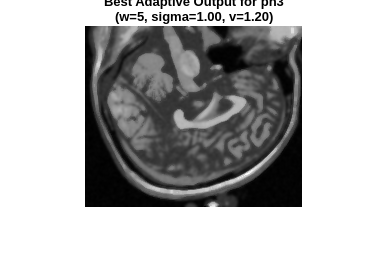

   SWEEPING PARAMETERS FOR pn5


w=5 | sigma=0.60 | var=0.70 -> PSNR=22.904 SSIM=0.7575 RMSE=0.0716
w=5 | sigma=0.60 | var=0.90 -> PSNR=22.930 SSIM=0.7627 RMSE=0.0714
w=5 | sigma=0.60 | var=1.00 -> PSNR=22.945 SSIM=0.7658 RMSE=0.0712
w=5 | sigma=0.60 | var=1.20 -> PSNR=23.653 SSIM=0.7756 RMSE=0.0657
w=5 | sigma=0.80 | var=0.70 -> PSNR=23.318 SSIM=0.7852 RMSE=0.0683
w=5 | sigma=0.80 | var=0.90 -> PSNR=23.357 SSIM=0.7908 RMSE=0.0679
w=5 | sigma=0.80 | var=1.00 -> PSNR=23.378 SSIM=0.7941 RMSE=0.0678
w=5 | sigma=0.80 | var=1.20 -> PSNR=23.429 SSIM=0.7991 RMSE=0.0674
w=5 | sigma=1.00 | var=0.70 -> PSNR=23.606 SSIM=0.7985 RMSE=0.0660
w=5 | sigma=1.00 | var=0.90 -> PSNR=23.648 SSIM=0.8031 RMSE=0.0657
w=5 | sigma=1.00 | var=1.00 -> PSNR=23.670 SSIM=0.8060 RMSE=0.0655
w=5 | sigma=1.00 | var=1.20 -> PSNR=23.719 SSIM=0.8102 RMSE=0.0652
w=5 | sigma=1.20 | var=0.70 -> PSNR=23.761 SSIM=0.8037 RMSE=0.0649
w=5 | sigma=1.20 | var=0.90 -> PSNR=23.798 SSIM=0.8071 RMSE=0.0646
w=5 | sigma=1.20 | var=1.00 -> PSNR=23.818 SSIM=0.8093 RMSE=0.


----- TOP 5 PARAMETER SETS FOR pn5 -----


    winSize    gaussSigma    varFactor     PSNR      SSIM        RMSE  
    _______    __________    _________    ______    _______    ________

       7          0.6           1.2       24.146    0.76469    0.062044
       5          1.4           1.2       23.883    0.80857    0.063949
       5          1.2           1.2        23.86    0.81231    0.064124
       5          1.4             1       23.851    0.80662    0.064187
       5          1.4           0.9       23.836    0.80501    0.064302




BEST PARAMETERS FOR pn5:


winSize    = 7


gaussSigma = 0.60


varFactor  = 1.20


PSNR       = 24.146


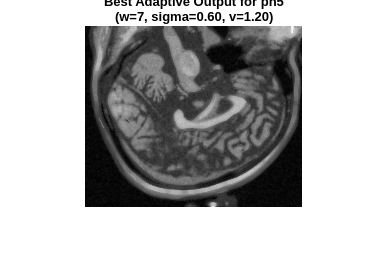

   SWEEPING PARAMETERS FOR pn9


w=5 | sigma=0.60 | var=0.70 -> PSNR=22.756 SSIM=0.6644 RMSE=0.0728
w=5 | sigma=0.60 | var=0.90 -> PSNR=24.027 SSIM=0.6807 RMSE=0.0629
w=5 | sigma=0.60 | var=1.00 -> PSNR=24.029 SSIM=0.6831 RMSE=0.0629
w=5 | sigma=0.60 | var=1.20 -> PSNR=24.044 SSIM=0.6868 RMSE=0.0628
w=5 | sigma=0.80 | var=0.70 -> PSNR=22.914 SSIM=0.6977 RMSE=0.0715
w=5 | sigma=0.80 | var=0.90 -> PSNR=25.134 SSIM=0.7273 RMSE=0.0554
w=5 | sigma=0.80 | var=1.00 -> PSNR=25.160 SSIM=0.7307 RMSE=0.0552
w=5 | sigma=0.80 | var=1.20 -> PSNR=25.213 SSIM=0.7360 RMSE=0.0549
w=5 | sigma=1.00 | var=0.70 -> PSNR=22.956 SSIM=0.7089 RMSE=0.0712
w=5 | sigma=1.00 | var=0.90 -> PSNR=25.945 SSIM=0.7486 RMSE=0.0504
w=5 | sigma=1.00 | var=1.00 -> PSNR=25.980 SSIM=0.7519 RMSE=0.0502
w=5 | sigma=1.00 | var=1.20 -> PSNR=26.050 SSIM=0.7569 RMSE=0.0498
w=5 | sigma=1.20 | var=0.70 -> PSNR=22.962 SSIM=0.7119 RMSE=0.0711
w=5 | sigma=1.20 | var=0.90 -> PSNR=26.448 SSIM=0.7590 RMSE=0.0476
w=5 | sigma=1.20 | var=1.00 -> PSNR=26.484 SSIM=0.7617 RMSE=0.


----- TOP 5 PARAMETER SETS FOR pn9 -----


    winSize    gaussSigma    varFactor     PSNR      SSIM        RMSE  
    _______    __________    _________    ______    _______    ________

       5          1.4           1.2       26.708    0.76684    0.046195
       5          1.2           1.2       26.554    0.76599    0.047022
       5          1.4             1       26.524    0.76104    0.047184
       5          1.4           0.9       26.495    0.75887    0.047341
       5          1.2             1       26.484    0.76174    0.047401




BEST PARAMETERS FOR pn9:


winSize    = 5


gaussSigma = 1.40


varFactor  = 1.20


PSNR       = 26.708


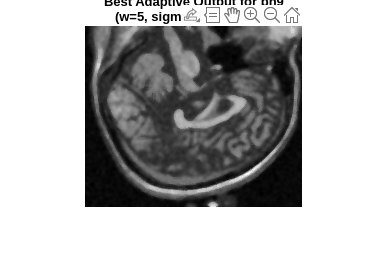

% Parameter ranges

winSizes    = [5, 7, 9, 11];
gaussSigmas = [0.6, 0.8, 1.0, 1.2, 1.4];
varFactors  = [0.7, 0.9, 1.0, 1.2];

% Loop over noise levels

for nl = noiseLevels

    fprintf("\n===============================\n");
    fprintf("   SWEEPING PARAMETERS FOR %s\n", nl);
    fprintf("===============================\n");

    noisyFile = "t1_icbm_normal_1mm_" + nl + "_rf0.nii";
    noisyVol  = load_brainweb_nifti(fullfile(dataDir, noisyFile));

    % Normalize noisy slice
    noisy = mat2gray(double(noisyVol(:,:,slice_idx)));

    best_psnr = -inf;
    best_img = [];
    best_params = [];

    idx = 1;
    results = struct();

  
    % Sweep combinations

    for w = winSizes
        for g = gaussSigmas
            for v = varFactors

                filtered = adaptive_hybrid_filter(noisy, w, g, v);
                filtered = mat2gray(filtered);   % normalize output

                % Metrics vs normalized clean image
                p = psnr(filtered, clean);
                s = ssim(filtered, clean);
                r = sqrt(immse(filtered, clean));

                results(idx).winSize    = w;
                results(idx).gaussSigma = g;
                results(idx).varFactor  = v;
                results(idx).PSNR       = p;
                results(idx).SSIM       = s;
                results(idx).RMSE       = r;

                % Print progress
                fprintf("w=%d | sigma=%.2f | var=%.2f -> PSNR=%.3f SSIM=%.4f RMSE=%.4f\n", ...
                    w, g, v, p, s, r);

                % Track best
                if p > best_psnr
                    best_psnr = p;
                    best_img = filtered;
                    best_params = [w, g, v];
                end

                idx = idx + 1;

            end
        end
    end
   
    % Display sorted results
   
    T = struct2table(results);
    T_sorted = sortrows(T, {'PSNR','SSIM','RMSE'}, {'descend','descend','ascend'});

    fprintf("\n----- TOP 5 PARAMETER SETS FOR %s -----\n", nl);
    disp(T_sorted(1:5,:));

    % Display best result
   
    fprintf("\nBEST PARAMETERS FOR %s:\n", nl);
    fprintf("winSize    = %d\n", best_params(1));
    fprintf("gaussSigma = %.2f\n", best_params(2));
    fprintf("varFactor  = %.2f\n", best_params(3));
    fprintf("PSNR       = %.3f\n", best_psnr);

    figure('Position',[300 200 600 600]);
    imshow(best_img, []);
    title(sprintf("Best Adaptive Output for %s\n(w=%d, sigma=%.2f, v=%.2f)", ...
        nl, best_params(1), best_params(2), best_params(3)));

end